syms K A u_r u_l  DJK DJI u_i u_j u_k u_m
F = (- 0.5*DJK*(u_j - u_i) + 0.5*DJI*(u_j - u_k));

## **The expression for DIJ is defined as follow:**

# 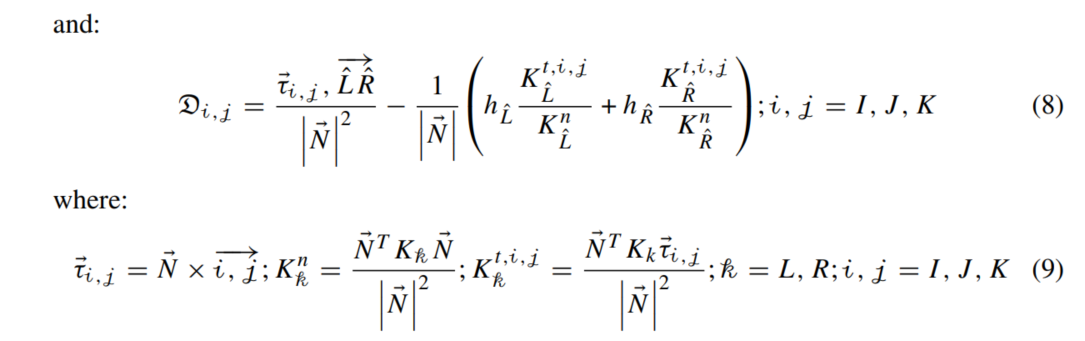

# **Total Flux Expression for Tetrahedron**

**The generalization of the TPFA terms of the MPFA-D is trivial. Therefore, we only need to study the CDT terms.**

**We start by defining the CDT terms of two tetrahedron sharing a common face IJK**

#### **IJK**

Fm = -K*A*collect(F,[u_r u_l u_i u_j u_k])

$$Fm = -A\,K\,\left(\frac{\mathrm{DJK}}{2}\,u_{i}+\left(\frac{\mathrm{DJI}}{2}-\frac{\mathrm{DJK}}{2}\right)\,u_{j}+\left(-\frac{\mathrm{DJI}}{2}\right)\,u_{k}\right)$$

The idea here is to generalize is to devide the area A of a polygon using as an auxiliary node the center of A. This way, for instance, we can divide a quadrilateral face IJKM into ICJ, JCK, KCM and MLCI. With respective areas A_1 A_2 A_3 A_4

## Flux in ICJ

**ICJ**

syms DCK DCM DCJ DCI DCJ u_c A_1 A_2 A_3 A_4
% I J
F_1 = (-0.5*DCJ*(u_c - u_i) + 0.5*DCI*(u_c - u_j));
F_IJ = -K*A_1*collect(F_1,[u_r u_l u_i u_c u_j])

$$F\_IJ = -A_{1}\,K\,\left(\frac{\mathrm{DCJ}}{2}\,u_{i}+\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCJ}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCI}}{2}\right)\,u_{j}\right)$$

## Flux in JCK

**JCK**

F_2 = (- 0.5*DCK*(u_c - u_j) + 0.5*DCJ*(u_c - u_k));
F_JK = -K*A_2*collect(F_2,[u_r u_l u_j u_c u_k u_m])

$$F\_JK = -A_{2}\,K\,\left(\frac{\mathrm{DCK}}{2}\,u_{j}+\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCK}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCJ}}{2}\right)\,u_{k}\right)$$

## Flux in KCM

**KCM**

F_3 = (- 0.5*DCM*(u_c - u_k) + 0.5*DCK*(u_c - u_m));
F_KM = -K*A_3*collect(F_3,[u_k u_c u_m])

$$F\_KM = -A_{3}\,K\,\left(\frac{\mathrm{DCM}}{2}\,u_{k}+\left(\frac{\mathrm{DCK}}{2}-\frac{\mathrm{DCM}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCK}}{2}\right)\,u_{m}\right)$$

## Flux in MCI

**MCI**

syms DCM
F_4 = (- 0.5*DCI*(u_c - u_m) + 0.5*DCM*(u_c - u_i));
F_MI = -K*A_4*collect(F_4,[u_m, u_c u_i])

$$F\_MI = -A_{4}\,K\,\left(\frac{\mathrm{DCI}}{2}\,u_{m}+\left(\frac{\mathrm{DCM}}{2}-\frac{\mathrm{DCI}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCM}}{2}\right)\,u_{i}\right)$$

## Flux CDT in IJKM

**IJKM**

**F = F_IJ + F_JK + F_KM + F_MI**

**where**

$A$** = **$A_1 + A_2 + A_3 + A_4$

%K I
%disp("K I")
F_total =  F_IJ + F_JK + F_KM + F_MI 

$$F\_total = -A_{1}\,K\,\left(\frac{\mathrm{DCJ}}{2}\,u_{i}+\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCJ}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCI}}{2}\right)\,u_{j}\right)-A_{2}\,K\,\left(\frac{\mathrm{DCK}}{2}\,u_{j}+\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCK}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCJ}}{2}\right)\,u_{k}\right)-A_{4}\,K\,\left(\frac{\mathrm{DCI}}{2}\,u_{m}+\left(\frac{\mathrm{DCM}}{2}-\frac{\mathrm{DCI}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCM}}{2}\right)\,u_{i}\right)-A_{3}\,K\,\left(\frac{\mathrm{DCM}}{2}\,u_{k}+\left(\frac{\mathrm{DCK}}{2}-\frac{\mathrm{DCM}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCK}}{2}\right)\,u_{m}\right)$$

%F_total = collect(expand(F_total), u_c)
F_n = (K/2)*collect((F_total*2/K), [u_i u_j u_k u_m u_c K])

$$F\_n = \frac{K\,\left(\left(A_{4}\,\mathrm{DCM}-A_{1}\,\mathrm{DCJ}\right)\,u_{i}+\left(A_{1}\,\mathrm{DCI}-A_{2}\,\mathrm{DCK}\right)\,u_{j}+\left(A_{2}\,\mathrm{DCJ}-A_{3}\,\mathrm{DCM}\right)\,u_{k}+\left(A_{3}\,\mathrm{DCK}-A_{4}\,\mathrm{DCI}\right)\,u_{m}+\left(A_{4}\,\mathrm{DCI}-A_{1}\,\mathrm{DCI}+A_{1}\,\mathrm{DCJ}-A_{2}\,\mathrm{DCJ}+A_{2}\,\mathrm{DCK}-A_{3}\,\mathrm{DCK}+A_{3}\,\mathrm{DCM}-A_{4}\,\mathrm{DCM}\right)\,u_{c}\right)}{2}$$

Playing with the coefficient of u_c. Ideially This would be zero but that does not seem to be the case.  By isolating the areas:

COEF = collect((A_4*DCI - A_1*DCI + A_1*DCJ - A_2*DCJ + A_2*DCK - A_3*DCK + A_3*DCM - A_4*DCM), [A_1,A_2 A_3 A_4])

$$COEF = \left(\mathrm{DCJ}-\mathrm{DCI}\right)\,A_{1}+\left(\mathrm{DCK}-\mathrm{DCJ}\right)\,A_{2}+\left(\mathrm{DCM}-\mathrm{DCK}\right)\,A_{3}+\left(\mathrm{DCI}-\mathrm{DCM}\right)\,A_{4}$$

OR ISOLATING **(DCI DCJ DCK DCM):**

COEF = collect((A_4*DCI - A_1*DCI + A_1*DCJ - A_2*DCJ + A_2*DCK - A_3*DCK + A_3*DCM - A_4*DCM), [DCI DCJ DCK DCM])

$$COEF = \left(A_{4}-A_{1}\right)\,\mathrm{DCI}+\left(A_{1}-A_{2}\right)\,\mathrm{DCJ}+\left(A_{2}-A_{3}\right)\,\mathrm{DCK}+\left(A_{3}-A_{4}\right)\,\mathrm{DCM}$$

However, u_c is not a degree of freedom. Therefore, we can define:

u_c = (u_i + u_j + u_k + u_m)/4

$$u\_c = \frac{u_{i}}{4}+\frac{u_{j}}{4}+\frac{u_{k}}{4}+\frac{u_{m}}{4}$$

By substituting in F_n, expnading and factoring for K/8, we have F_cdt_hexadro

F_cdt_hexadro = collect(expand((8/K)*subs(F_n,u_c)),[u_i u_j u_k u_m])

$$F\_cdt\_hexadro = \left(A_{4}\,\mathrm{DCI}-A_{1}\,\mathrm{DCI}-3\,A_{1}\,\mathrm{DCJ}-A_{2}\,\mathrm{DCJ}+A_{2}\,\mathrm{DCK}-A_{3}\,\mathrm{DCK}+A_{3}\,\mathrm{DCM}+3\,A_{4}\,\mathrm{DCM}\right)\,u_{i}+\left(3\,A_{1}\,\mathrm{DCI}+A_{4}\,\mathrm{DCI}+A_{1}\,\mathrm{DCJ}-A_{2}\,\mathrm{DCJ}-3\,A_{2}\,\mathrm{DCK}-A_{3}\,\mathrm{DCK}+A_{3}\,\mathrm{DCM}-A_{4}\,\mathrm{DCM}\right)\,u_{j}+\left(A_{4}\,\mathrm{DCI}-A_{1}\,\mathrm{DCI}+A_{1}\,\mathrm{DCJ}+3\,A_{2}\,\mathrm{DCJ}+A_{2}\,\mathrm{DCK}-A_{3}\,\mathrm{DCK}-3\,A_{3}\,\mathrm{DCM}-A_{4}\,\mathrm{DCM}\right)\,u_{k}+\left(A_{1}\,\mathrm{DCJ}-3\,A_{4}\,\mathrm{DCI}-A_{1}\,\mathrm{DCI}-A_{2}\,\mathrm{DCJ}+A_{2}\,\mathrm{DCK}+3\,A_{3}\,\mathrm{DCK}+A_{3}\,\mathrm{DCM}-A_{4}\,\mathrm{DCM}\right)\,u_{m}$$

where F_n = (K/8) * F_cdt_hexaedro (THIS WAS DONE BECAUSE I COULDNT FACTOR K/8 WITHOUT MESSING THE REST OF THE EQUATUION)

manipulaing the terms associated with u_i, u_j, u_k, u_m respectivelly, we have:

## **u_i**

T_i = A_4*DCI - A_1*DCI - 3*A_1*DCJ - A_2*DCJ + A_2*DCK - A_3*DCK + A_3*DCM + 3*A_4*DCM

$$T\_i = A_{4}\,\mathrm{DCI}-A_{1}\,\mathrm{DCI}-3\,A_{1}\,\mathrm{DCJ}-A_{2}\,\mathrm{DCJ}+A_{2}\,\mathrm{DCK}-A_{3}\,\mathrm{DCK}+A_{3}\,\mathrm{DCM}+3\,A_{4}\,\mathrm{DCM}$$

T_i = collect(T_i, [DCI, DCJ, DCK, DCM])

$$T\_i = \left(A_{4}-A_{1}\right)\,\mathrm{DCI}+\left(-3\,A_{1}-A_{2}\right)\,\mathrm{DCJ}+\left(A_{2}-A_{3}\right)\,\mathrm{DCK}+\left(A_{3}+3\,A_{4}\right)\,\mathrm{DCM}$$

## **u_j**

T_j = (3*A_1*DCI + A_4*DCI + A_1*DCJ - A_2*DCJ - 3*A_2*DCK - A_3*DCK + A_3*DCM - A_4*DCM)

$$T\_j = 3\,A_{1}\,\mathrm{DCI}+A_{4}\,\mathrm{DCI}+A_{1}\,\mathrm{DCJ}-A_{2}\,\mathrm{DCJ}-3\,A_{2}\,\mathrm{DCK}-A_{3}\,\mathrm{DCK}+A_{3}\,\mathrm{DCM}-A_{4}\,\mathrm{DCM}$$

T_j = collect(T_j, [DCI, DCJ, DCK, DCM])

$$T\_j = \left(3\,A_{1}+A_{4}\right)\,\mathrm{DCI}+\left(A_{1}-A_{2}\right)\,\mathrm{DCJ}+\left(-3\,A_{2}-A_{3}\right)\,\mathrm{DCK}+\left(A_{3}-A_{4}\right)\,\mathrm{DCM}$$

## **u_k**

T_k =  (A_4*DCI - A_1*DCI + A_1*DCJ + 3*A_2*DCJ + A_2*DCK - A_3*DCK - 3*A_3*DCM - A_4*DCM)

$$T\_k = A_{4}\,\mathrm{DCI}-A_{1}\,\mathrm{DCI}+A_{1}\,\mathrm{DCJ}+3\,A_{2}\,\mathrm{DCJ}+A_{2}\,\mathrm{DCK}-A_{3}\,\mathrm{DCK}-3\,A_{3}\,\mathrm{DCM}-A_{4}\,\mathrm{DCM}$$

T_k = collect(T_k, [DCI, DCJ, DCK, DCM])

$$T\_k = \left(A_{4}-A_{1}\right)\,\mathrm{DCI}+\left(A_{1}+3\,A_{2}\right)\,\mathrm{DCJ}+\left(A_{2}-A_{3}\right)\,\mathrm{DCK}+\left(-3\,A_{3}-A_{4}\right)\,\mathrm{DCM}$$

## **u_m**

T_u = (A_1*DCJ - 3*A_4*DCI - A_1*DCI - A_2*DCJ + A_2*DCK + 3*A_3*DCK + A_3*DCM - A_4*DCM)

$$T\_u = A_{1}\,\mathrm{DCJ}-3\,A_{4}\,\mathrm{DCI}-A_{1}\,\mathrm{DCI}-A_{2}\,\mathrm{DCJ}+A_{2}\,\mathrm{DCK}+3\,A_{3}\,\mathrm{DCK}+A_{3}\,\mathrm{DCM}-A_{4}\,\mathrm{DCM}$$

T_u = collect(T_u, [DCI, DCJ, DCK, DCM])

$$T\_u = \left(-A_{1}-3\,A_{4}\right)\,\mathrm{DCI}+\left(A_{1}-A_{2}\right)\,\mathrm{DCJ}+\left(A_{2}+3\,A_{3}\right)\,\mathrm{DCK}+\left(A_{3}-A_{4}\right)\,\mathrm{DCM}$$

## We define a more neat version of the flux across a quadrilateral face:

syms TT_i TT_j TT_k TT_m
F_neat = collect(-(K/8)*(TT_i*u_i + TT_j*u_j + TT_k*u_k + TT_m*u_m),[u_i u_j u_k u_m])

$$F\_neat = \left(-\frac{K\,{\mathrm{TT}}_{i}}{8}\right)\,u_{i}+\left(-\frac{K\,{\mathrm{TT}}_{j}}{8}\right)\,u_{j}+\left(-\frac{K\,{\mathrm{TT}}_{k}}{8}\right)\,u_{k}+\left(-\frac{K\,{\mathrm{TT}}_{m}}{8}\right)\,u_{m}$$

#### where TT_i TT_j TT_k TT_m defined as above